## Regularization

Q:What is **Regularization**?

A: **Regularization** is a technique that **prevents the model from overfitting **on the data by adding a penalty to the weights of model.

Q: What types of regularization exists?

A: There are **3 **main types of **regularization:**

- **Lasso **or **L1 norm**

- **Ridge **or **L2 norm**

- **Dropout**, which we will see in **Deep learning.**

load carbig
feature_names = ["Acceleration" "Weight" "Displacement" "Horsepower"];
feature_names = ["Acceleration" "Weight" "Displacement" "Horsepower"];
X = [Acceleration Weight Displacement Horsepower];
y = MPG;


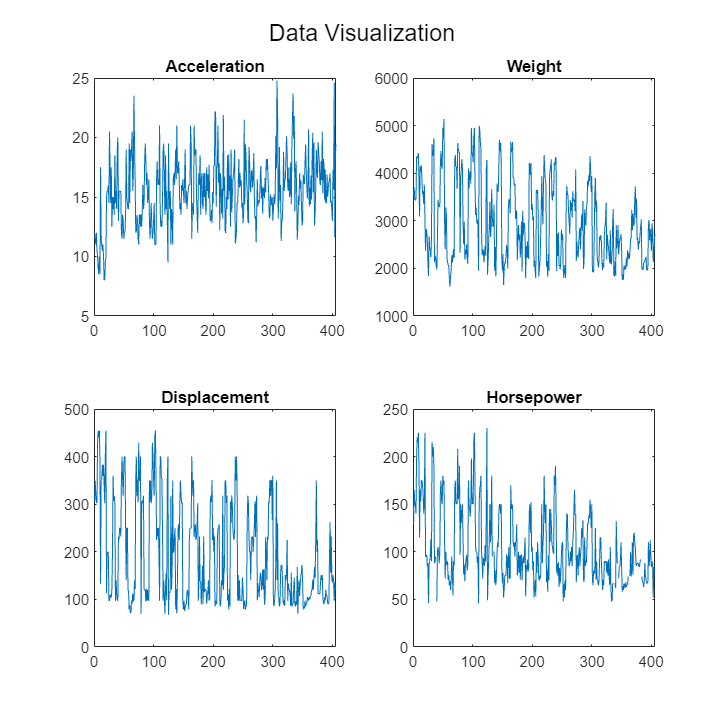

% Visualize the data 
f = figure;
f.Position(3:4) = [1080, 1080];
%f.set
sgtitle("Data Visualization")

for feature=1:4
    
    subplot(2, 2, feature)
    p=plot(X(:,feature));
    title(feature_names(feature))
    p.DisplayName = feature_names(feature);
    xlabel("Data point")
    ylabel(feature_units(feature))
end

figure
gplotmatrix(X,[],Cylinders,['c' 'b' 'm' 'g' 'r'],[],[],false);
text([.08 .24 .43 .66 .83], repmat(-.1,1,5), varNames, 'FontSize',8);
text(repmat(-.12,1,5), [.86 .62 .41 .25 .02], varNames, 'FontSize',8, 'Rotation',90);

n = length(y);
rng('default') % For reproducibility
c = cvpartition(n,'HoldOut',0.3);
idxTrain = training(c,1);
idxTest = ~idxTrain;

k = 5;
b = ridge(y(idxTrain),X(idxTrain,:),k,0);